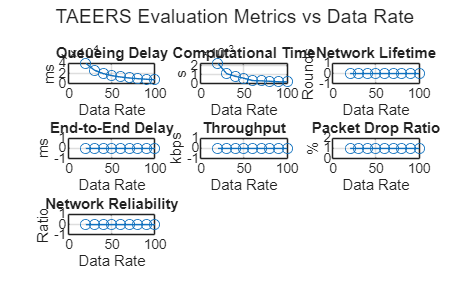

% TAEERS Routing Protocol for WBASN - MATLAB Implementation
clc; clear;

%% Network Parameters
areaSize = 250;                 % cm (2.5m x 2.5m)
numRelays = 7;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;  % Total = 16
range = 50;                     % cm
initialEnergy = 7;              % Joules
energyThreshold = 0.2 * initialEnergy;
tempLow = 39;                   % Low temp threshold
tempHigh = 40;                  % High temp threshold
packetSize = 3000 / 8;          % bits to bytes
dataRates = 20:10:100;         % kbps
simTime = 1000;                 % seconds
queueDelayBase = 5; queueVar = 10;
frequency = 2.4e9;              % Hz
wavelength = 0.138;             % m

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;

%% Load Sensor Data (HR, BP, BT, RR, BS, SPO2, EDA, BVP)
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) ~= numSources
    error('Expected 8 columns of sensor data for 8 source nodes.');
end

%% Metrics Initialization
energyPerSource = zeros(length(dataRates), numSources);
metrics = zeros(length(dataRates), 7); % QueueDelay, Time, Lifetime, E2EDelay, Throughput, DropRatio, Reliability

%% Start Simulation
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);

    totalQueueDelay = 0;
    totalE2EDelay = zeros(size(sensorData,1), 1);
    networkLifetime = 0;
    tStart = tic;

    totalPacketsSent = 0;
    totalPacketsReceived = 0;
    totalPacketsDropped = 0;

    for t = 1:size(sensorData, 1)
        roundE2EDelay = 0; validCount = 0;

        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            dataValue = sensorData(t, s);
            tempValue = sensorData(t, 3); % Body Temperature from Source 3
            isCritical = (s == 3 && tempValue >= tempHigh);

            totalPacketsSent = totalPacketsSent + 1;

            if isCritical
                % Direct transmission to sink
                distToSink = norm(positions(srcID,:) - positions(sinkID,:));
                delay = rand() * 100 + distToSink * 0.1;
                roundE2EDelay = roundE2EDelay + delay;
                energy(srcID) = energy(srcID) - 0.1;

                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                    totalPacketsDropped = totalPacketsDropped + 1;
                else
                    totalPacketsReceived = totalPacketsReceived + 1;
                end
            elseif tempValue >= tempLow && tempValue < tempHigh
                % Relay transmission (critical but not very high)
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligibleRelays = find(dists <= range & roles == "Relay" & ~nodeDead);

                if isempty(eligibleRelays)
                    totalPacketsDropped = totalPacketsDropped + 1;
                    continue;
                end

                if all(eligibleRelays <= numNodes)
                    [~, localIdx] = min(dists(eligibleRelays));
                    relayID = eligibleRelays(localIdx);

                    if relayID <= numNodes && srcID <= numNodes
                        delay = rand() * queueVar + queueDelayBase;
                        roundE2EDelay = roundE2EDelay + delay;

                        energy(srcID) = energy(srcID) - 0.05;
                        energy(relayID) = energy(relayID) - 0.05;

                        if energy(srcID) < energyThreshold, nodeDead(srcID) = true; end
                        if energy(relayID) < energyThreshold, nodeDead(relayID) = true; end

                        if nodeDead(srcID) || nodeDead(relayID)
                            totalPacketsDropped = totalPacketsDropped + 1;
                        else
                            totalPacketsReceived = totalPacketsReceived + 1;
                        end
                    else
                        totalPacketsDropped = totalPacketsDropped + 1;
                    end
                else
                    totalPacketsDropped = totalPacketsDropped + 1;
                end
            else
                % Drop repeated/non-critical normal data
                totalPacketsDropped = totalPacketsDropped + 1;
            end

            if networkLifetime == 0 && any(energy < energyThreshold)
                networkLifetime = t;
            end

            totalQueueDelay = totalQueueDelay + queueDelayBase;
            validCount = validCount + 1;
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    tComp = toc(tStart) / dataRate;
    throughput = (totalPacketsReceived * packetSize * 8) / (simTime * 1000);
    dropRatio = totalPacketsDropped / totalPacketsSent;
    reliability = totalPacketsReceived / totalPacketsSent;

    metrics(drIdx,:) = [
        totalQueueDelay / dataRate, ...
        tComp, ...
        networkLifetime / dataRate, ...
        mean(totalE2EDelay(~isnan(totalE2EDelay))), ...
        throughput, ...
        dropRatio, ...
        reliability
    ];

    for s = 1:numSources
        srcID = numRelays + s;
        if srcID <= length(energy)
            energyPerSource(drIdx,s) = initialEnergy - energy(srcID);
        end
    end
end

%% Save Metrics
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_TAEERS.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_TAEERS.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_TAEERS.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_TAEERS.csv');
writematrix([dataRates(:), metrics(:,5)], 'Throughput_TAEERS.csv');
writematrix([dataRates(:), metrics(:,6)], 'Packet_Drop_Ratio_TAEERS.csv');
writematrix([dataRates(:), metrics(:,7)], 'Reliability_TAEERS.csv');
writematrix(energyPerSource, 'Energy_Source_Node_TAEERS.csv');

%% Plot Results
figure;
subplot(3,3,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,3,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(3,3,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Rounds'); grid on;
subplot(3,3,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,3,5); plot(dataRates, metrics(:,5), '-o'); title('Throughput'); xlabel('Data Rate'); ylabel('kbps'); grid on;
subplot(3,3,6); plot(dataRates, metrics(:,6), '-o'); title('Packet Drop Ratio'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,3,7); plot(dataRates, metrics(:,7), '-o'); title('Network Reliability'); xlabel('Data Rate'); ylabel('Ratio'); grid on;
sgtitle('TAEERS Evaluation Metrics vs Data Rate');

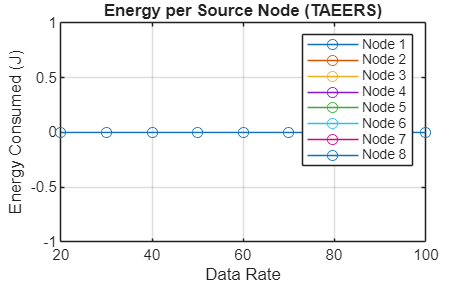


figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node (TAEERS)'); grid on; legend show;